# Tutorial:

# Using Transfer Learning to Train and Test Camera Designs

- Learn about Matlab's Deep Learning Designer

- Importing and processing Image Datasets

- Implementing Transfer Learning using Squeezenet

- Saving, Loading, and testing simulated cameras created with ISET

Assumes you are already familiar with the basics of using ISET, and the general topic of using neural networks for image recognition, as covered in class and recorded in [this video](https://stanford-pilot.hosted.panopto.com/Panopto/Pages/Viewer.aspx?id=13f9fd45-4b17-4ad1-8778-ac400180b690).

**Author: David Cardinal**

**For: Psych 221 Fall 2020**

In class and from the course videos, you've you've been learning how to create a camera design using ISET functions -- and hopefully develop some idea of how various design parameters in the optics, sensor, and imaging pipeline affect camera performance. In addition to seeing how well your camera performs on standard "human" metrics, you might be interested in thinking about how well various camera designs do when used for machine vision and robotics applications such as autonomous driving.

In our video lesson on using the ISET Camera Design application we talked through using the app as one way to create a camera design (Optics, Sensor, and Imaging Pipeline), and then evaluate how well the output of that camera compares to native images when using an object classifier to identify the subject of a set of test images. (For more in the ISET Camera Design Application, [here is the Psych 221 Video describing its use](https://stanford-pilot.hosted.panopto.com/Panopto/Pages/Viewer.aspx?id=13f9fd45-4b17-4ad1-8778-ac400180b690)). If you want to use the Camera Design app to design and test your camera with a pre-trained network, it has the pieces you need:

ieCameraDesigner

However, you may be wondering whether, instead of using a network that was trained entirely on images captured with a standard camera, you could improve our results by training your network on images captured with your novel camera design. This lesson will help you learn to do that and evaluate the results. While it is typically too long and expensive a process to train a sophisticated classifier from scratch, there is a powerful method called transfer learning that allows us to get most of those benefits with a lot less work.

*NOTE: If you simply want to experiment with Transfer Learning, you don't need to create a camera design at all. The Classifier script will create a default set of optics, sensor, and IP for you.*

# Get Started with Transfer Learning

This lesson will walk you through using transfer learning to retrain SqueezeNet, a pre-trained convolutional neural network, to improve its ability to identify objects in images taken with your camera design. (Squeezenet is an optimized version of the popular Alexnet that runs a lot faster). 

Transfer Learning involves starting with a pre-trained network and adapting it to new data. In this case the new data is the images captured by your camera design. Teaching a network using transfer learning is much faster and easier than training it from scratch. We can fairly quickly transfer learned features to our new task using a smaller number of training images than would be needed for the full training process. 

The principle behind the effectiveness of transfer learning is a discovery over time that the extracted "features" of most different kinds of images wind up being mostly-independent of the subject matter and how it was captured. Low-level features might include edges, and higher level features faces, for example. As a result, it is often possible to get dramatic improvements by keeping the expensive-to-train feature layers of a deep neural network (which is most of them), and simply replacing the final layers that do the classification and compute the loss function (score) of the network.

SIDEBAR: The reason we have to replace layers is that we usually have data in different classes from the original dataset (in the case of most pre-trained image recognition networks they usually are designed to identify the 1000 classes of ImageNet). If you just want to test a new camera or algorithm using the same dataset and classes, that's typically called fine-tuning, and is a simpler version of the process, as you don't need to replace layers, only tweak learning rates.

# Steps for Creating and Training Your Custom Network 

First we'll assemble the data we want to use. Then we'll load a pre-trained network to start with. Next, we'll replace its final layers, followed by training the modified network on our data. Finally we'll evaluate the results of our training process by looking at how well our network performs on the data we set aside to validate it:

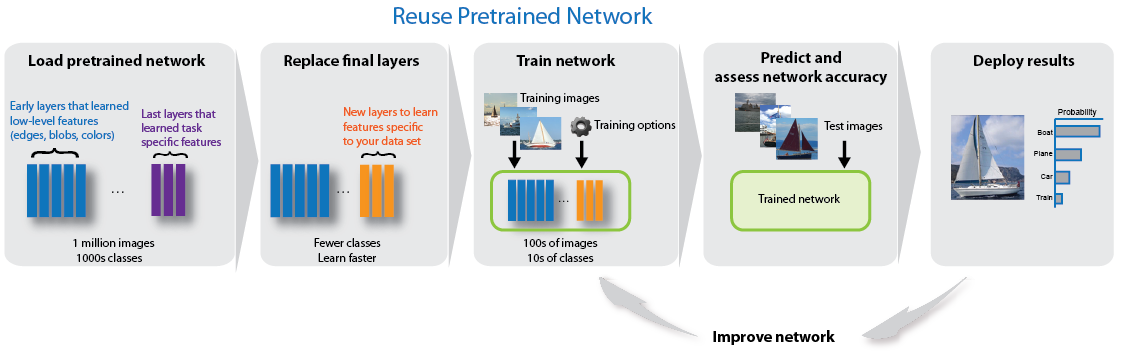

## First: Load Your Image Data

By default, Matlab's DeepNetworkDesigner assumes that you have a folder with all your data, separated into sub-folders each named after the class of images they contain. To keep things simple, we'll use the same organization. You'll likely want to supply your own data as you experiment, but to get you started we've provided an African mammal dataset you can use.

localDataStore = fullfile(isetRootPath, "local", "data");   
if ~isfolder(localDataStore)
                mkdir(localDataStore);
end
% Canvas can be slow, so we'll set a longer timeout
options = weboptions('Timeout',25);
websave(fullfile(localDataStore,'mammals.zip'),'https://canvas.stanford.edu/files/6540020/download?download_frd=1', options);
unzip(fullfile(localDataStore,'mammals.zip'), localDataStore);
ourDataFolder = fullfile(localDataStore, 'DavidCardinal_AfricanMammals/');

## **Load the Squeezenet Pre-trained Network**

Next we load a pre-trained network (in this case Squeezenet) using the Matlab Open Deep Network Designer. If you get an error when trying to launch it you may need to load it from the Apps tab in the main Matlab interface.

deepNetworkDesigner

Select **SqueezeNet** from the list of pre-trained networks and click **Open**. 

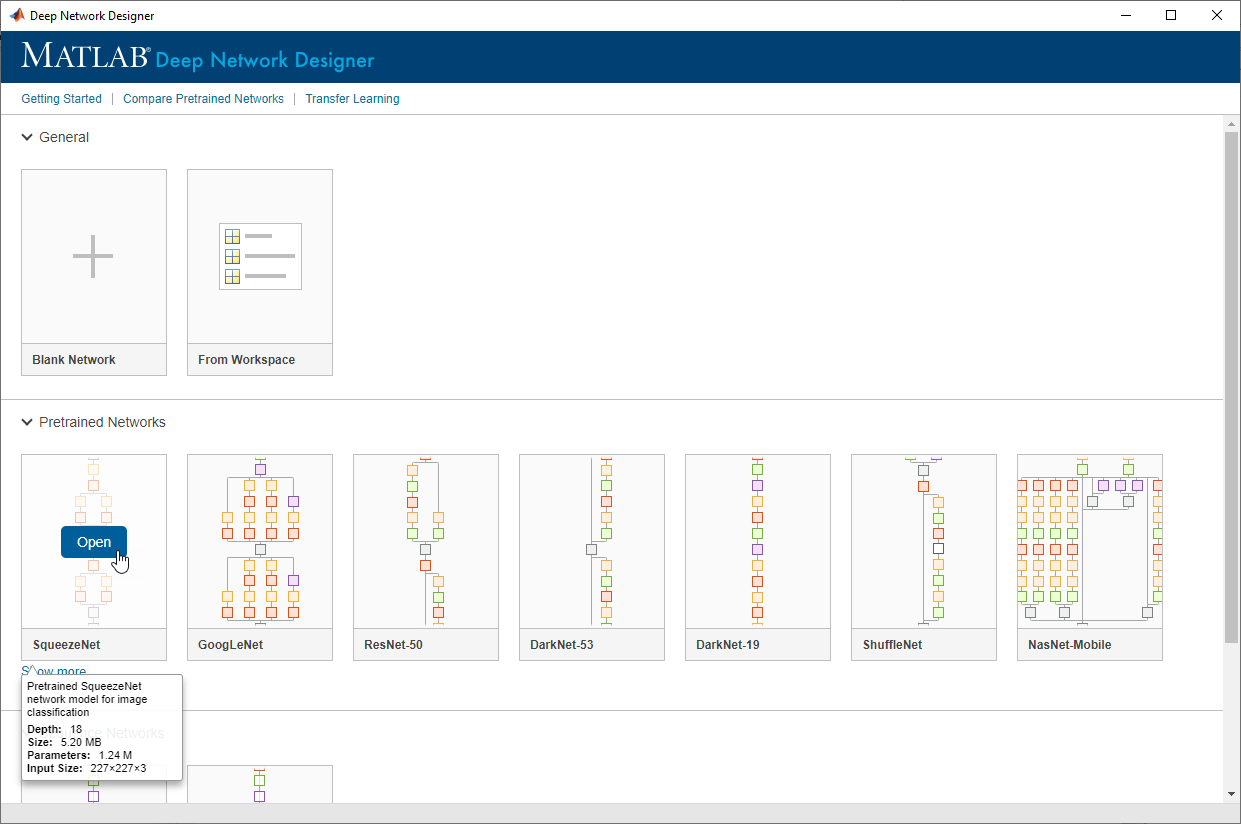

Deep Network Designer displays a zoomed-out view of the whole network. You'll see that even this slightly-simplified network has 68 layers and over a million parameters, so training it from scratch takes a long time. However, we are only going to need to work with two of the very last layers.

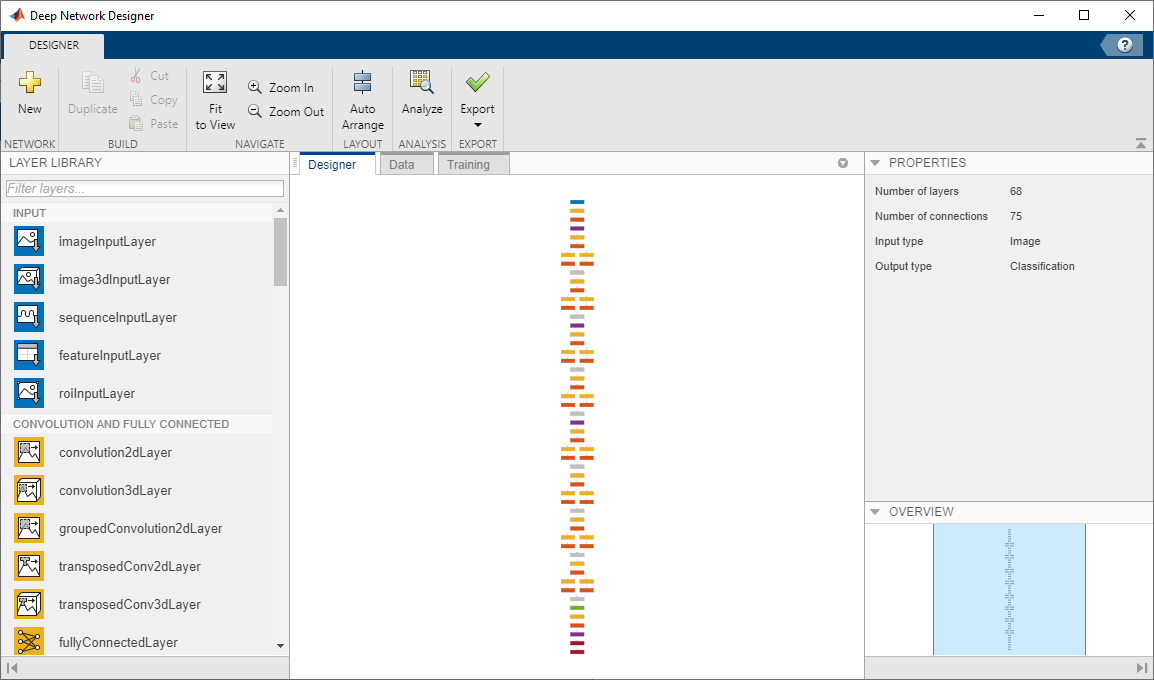

Explore the network plot. To zoom in with the mouse, use **Ctrl**+scroll wheel. To pan, use the arrow keys, or hold down the scroll wheel and drag the mouse. Select a layer to view its properties. Deselect all layers to view the network summary in the **Properties** pane. After you import your image data, we'll come back here to replace two of the layers.

## Import Your Images Using the Data Tab

To load your image data into Deep Network Designer, on the **Data** tab, click **Import Data** >** Import Image Data**. The Import Image Data dialog box opens.

In the **Data source** list, select **Folder**. Click **Browse** and select folder where you downloaded the mammals dataset, or whichever other data you are planning to use (*Don't click Import yet, though, as we have a couple more things to do*). If you simply ran the code above, the folder location should be the output of this command:

fullfile(localDataStore, 'DavidCardinal_AfricanMammals/')

Before we import our data, there are two important things we need to do first -- Set aside some data for validation, and augment our data to provide more variety to our network:

#### Set aside a Validation Dataset

To verify that our network is actually "learning" we split our labeled data into a training set -- from which it learns -- and a validation set -- which we use to give it a "closed book" test. A good general split is to divide the data into 70% training data and 30% validation data. By default the Import dialog should also default to 30%.

#### Create Augmented Images to Supplement Your Data

In case we don't have as many labeled images as we wish we had, we can specify augmentation operations to perform on the training images. Basically we let Matlab create sensible versions of our images to expand the number of them we have to use for training. Data augmentation helps prevent the network from overfitting and memorizing the exact details of the training images. For this example, you can apply a random reflection in the x-axis, a random rotation from the range [-90,90] degrees, and a random rescaling from the range [1,2]. We don't reflect on the y-axis since it isn't particularly realistic for most animal images to be shot upside down.

Here is what the import dialog should look like once you've done those two things:

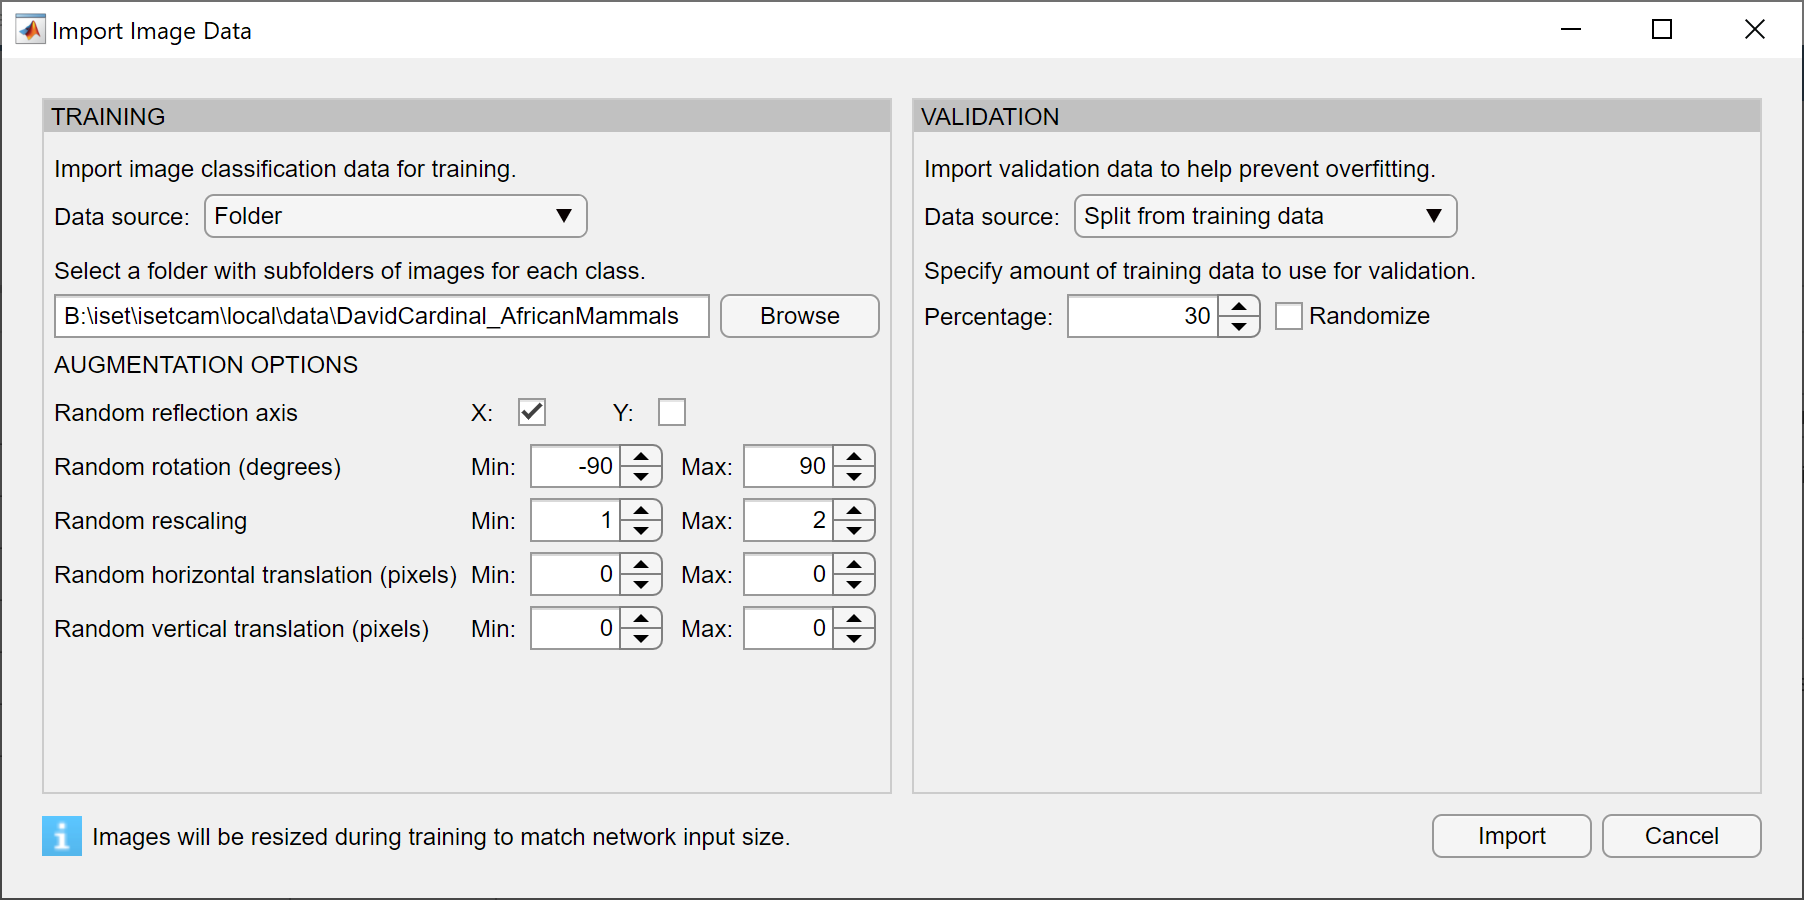

When you're ready, click **Import** to import the data into Deep Network Designer. You should see an informative display with some information about the data you've just imported, like this one:

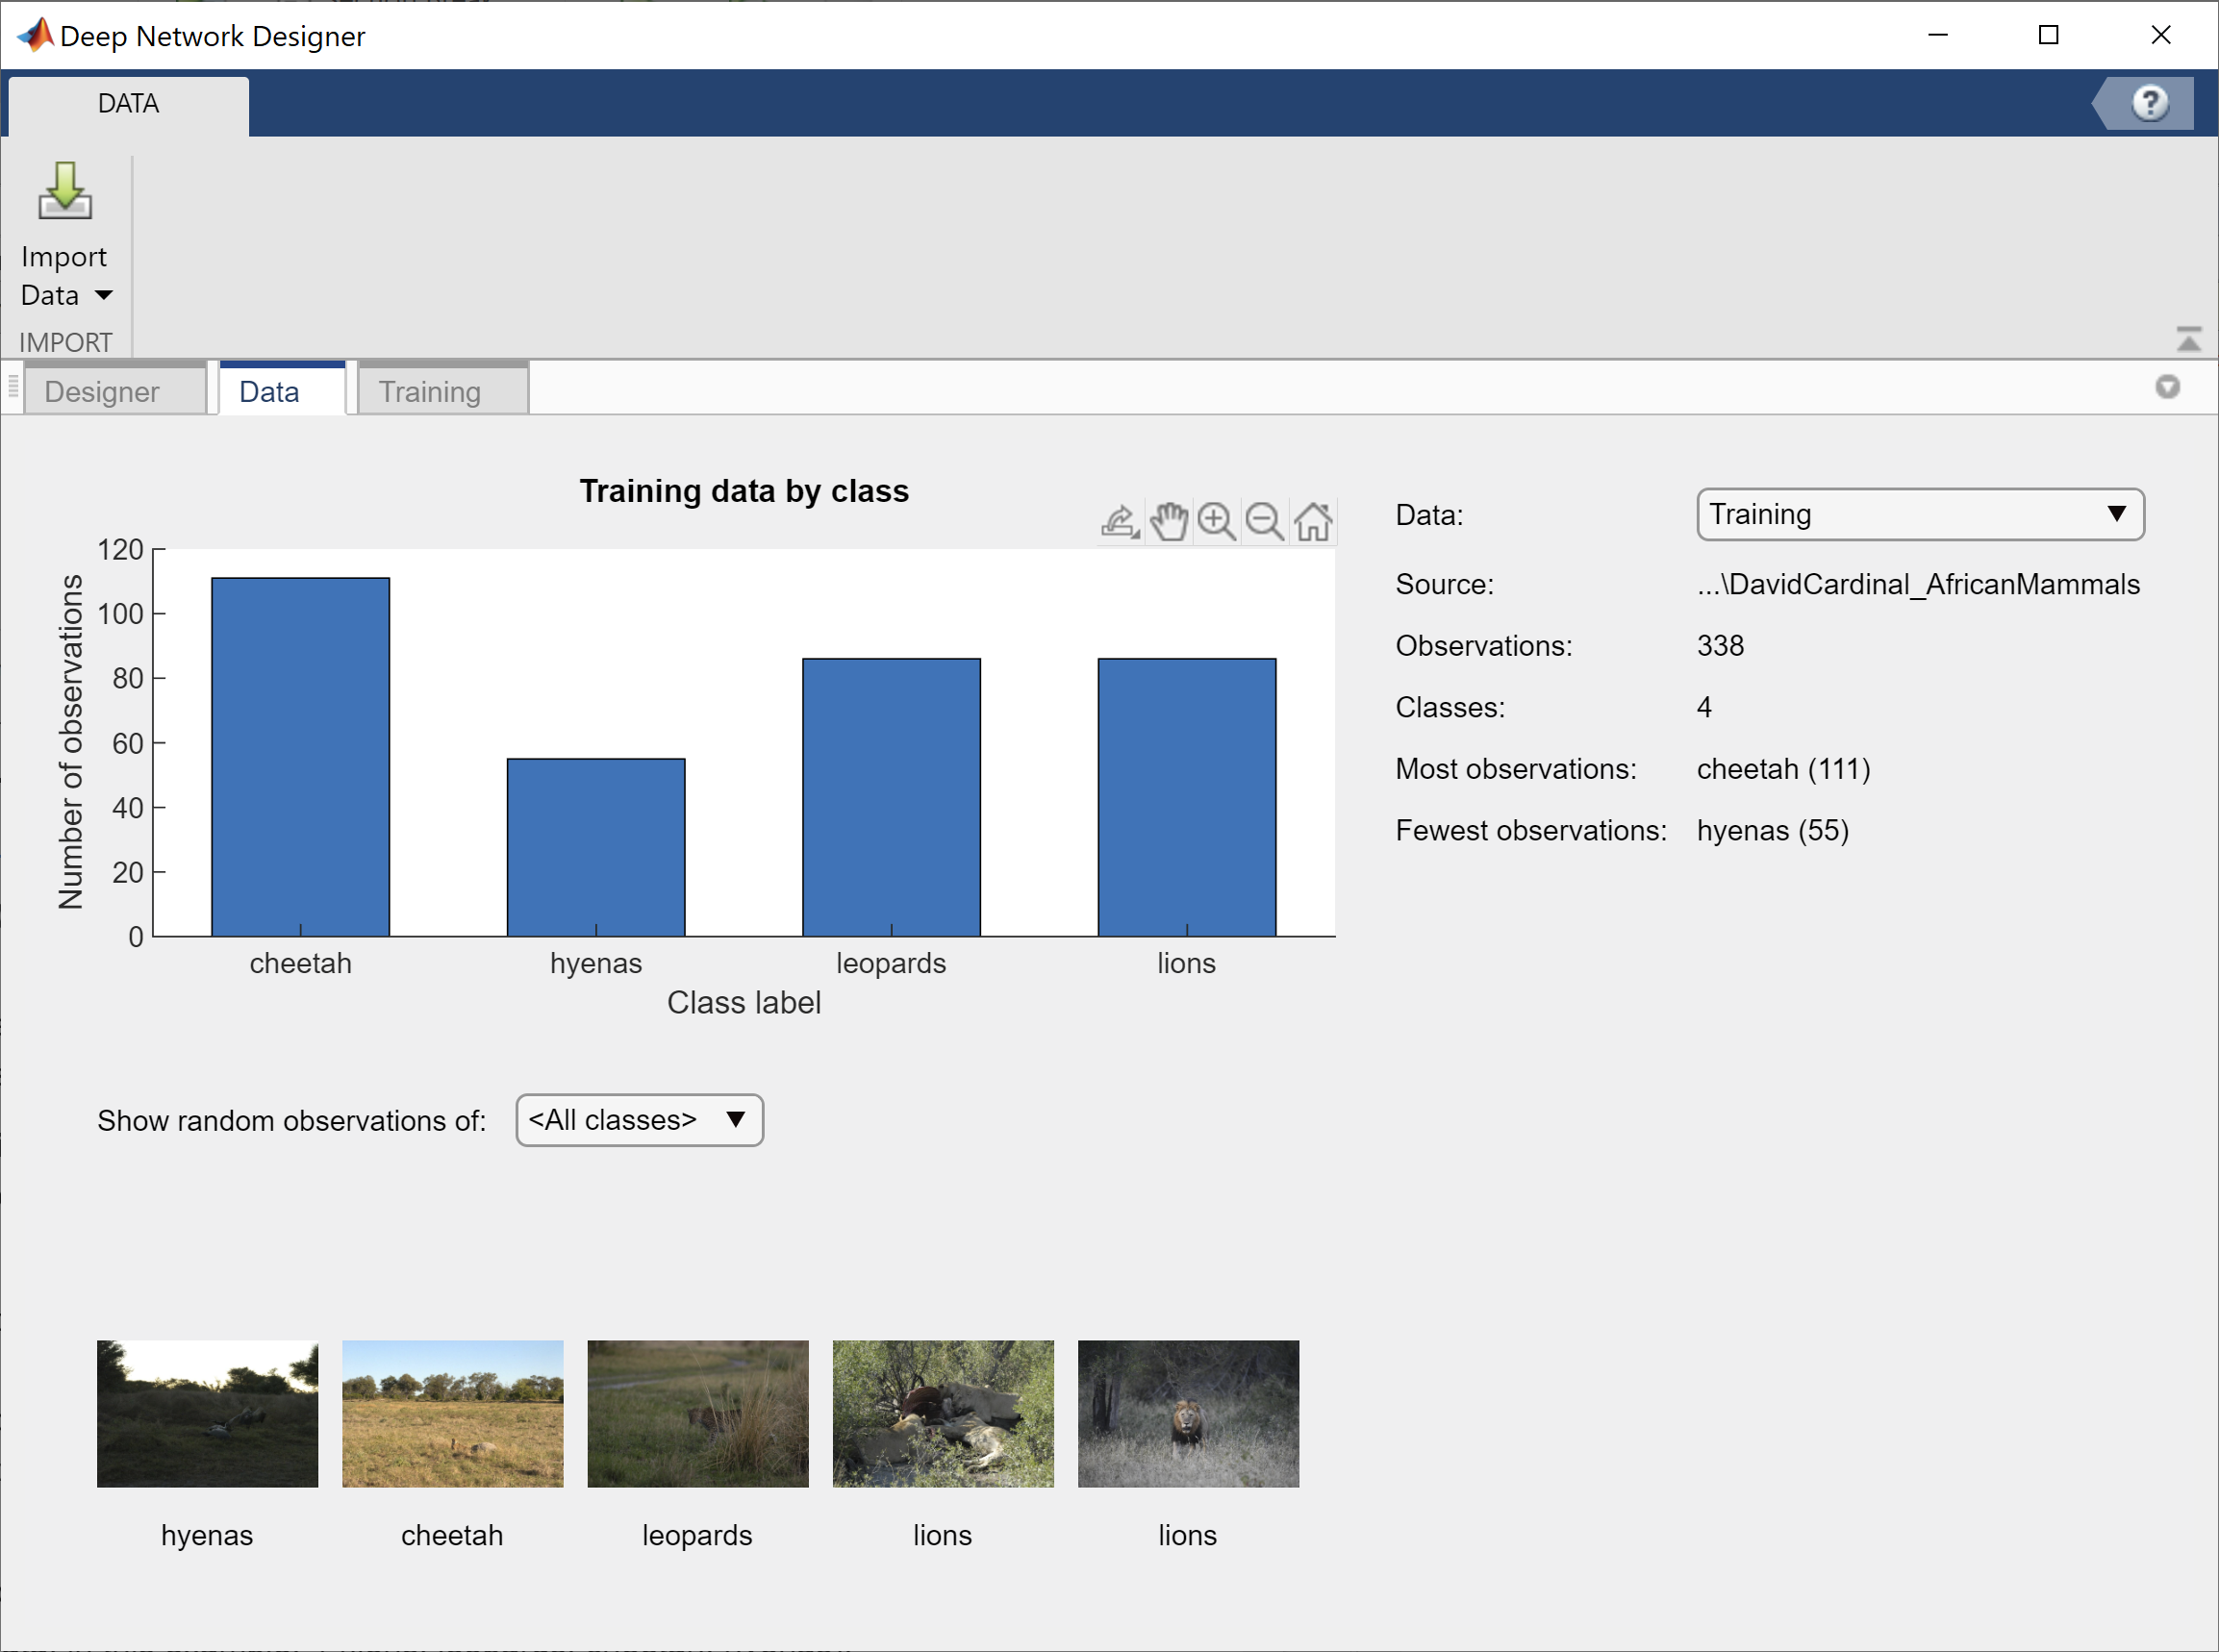

## **Edit Your Network for Transfer Learning**

Nex, to use transfer learning, we need to replace the final convolution layer of our pre-trained network so that it generates the correct number of classes for our dataset, and then replace the final classification layer that chooses between them. For example, Squeezenet and most classic object recognition networks are trained to choose between 1000 pre-defined classes of the ImageNet dataset, but we only have 4 in our test data.

So to get ready to retrain SqueezeNet to classify new images, we need to replace the last 2D convolutional layer and the final classification layer of the network. In Matlab's implementation of SqueezeNet, these layers have the names `'conv10'` and  `'ClassificationLayer_predictions'`, respectively. Those are the ones we need to replace.

Replacing layers in the Deep Learning Designer is a fairly simple "point and click" process. You simply drag a layer of the desired type from the layer palette to the network area, delete the old layer, and then click on the "output" port of the previous layer and drag it to the "input" port of your new layer. Then do the reverse, clicking on the "output" port of your new layer and connecting it to the "input" port of the layer that should follow it. 

#### Swapping out the final Convolution Layer

So to replace the final convolutional layer, start by switching to the **Designer** tab of the Deep Learning Designer. Then, drag a new `convolution2dLayer` onto the canvas. To match the original convolutional layer, set `FilterSize` to `1,1`. Edit `NumFilters` to be the number of classes in the new data, in this example, 4 (lions, leopards, cheetah, hyenas). We want to make sure our new layer gets smart, fast. So we'll change its learning rates so that learning is faster for it by setting `WeightLearnRateFactor` and `BiasLearnRateFactor` for our new layer to `10`.

Now, delete the last 2-D convolutional layer (probably named conv10) and connect your new layer instead. Here I've also renamed our new layer "ourLayer":

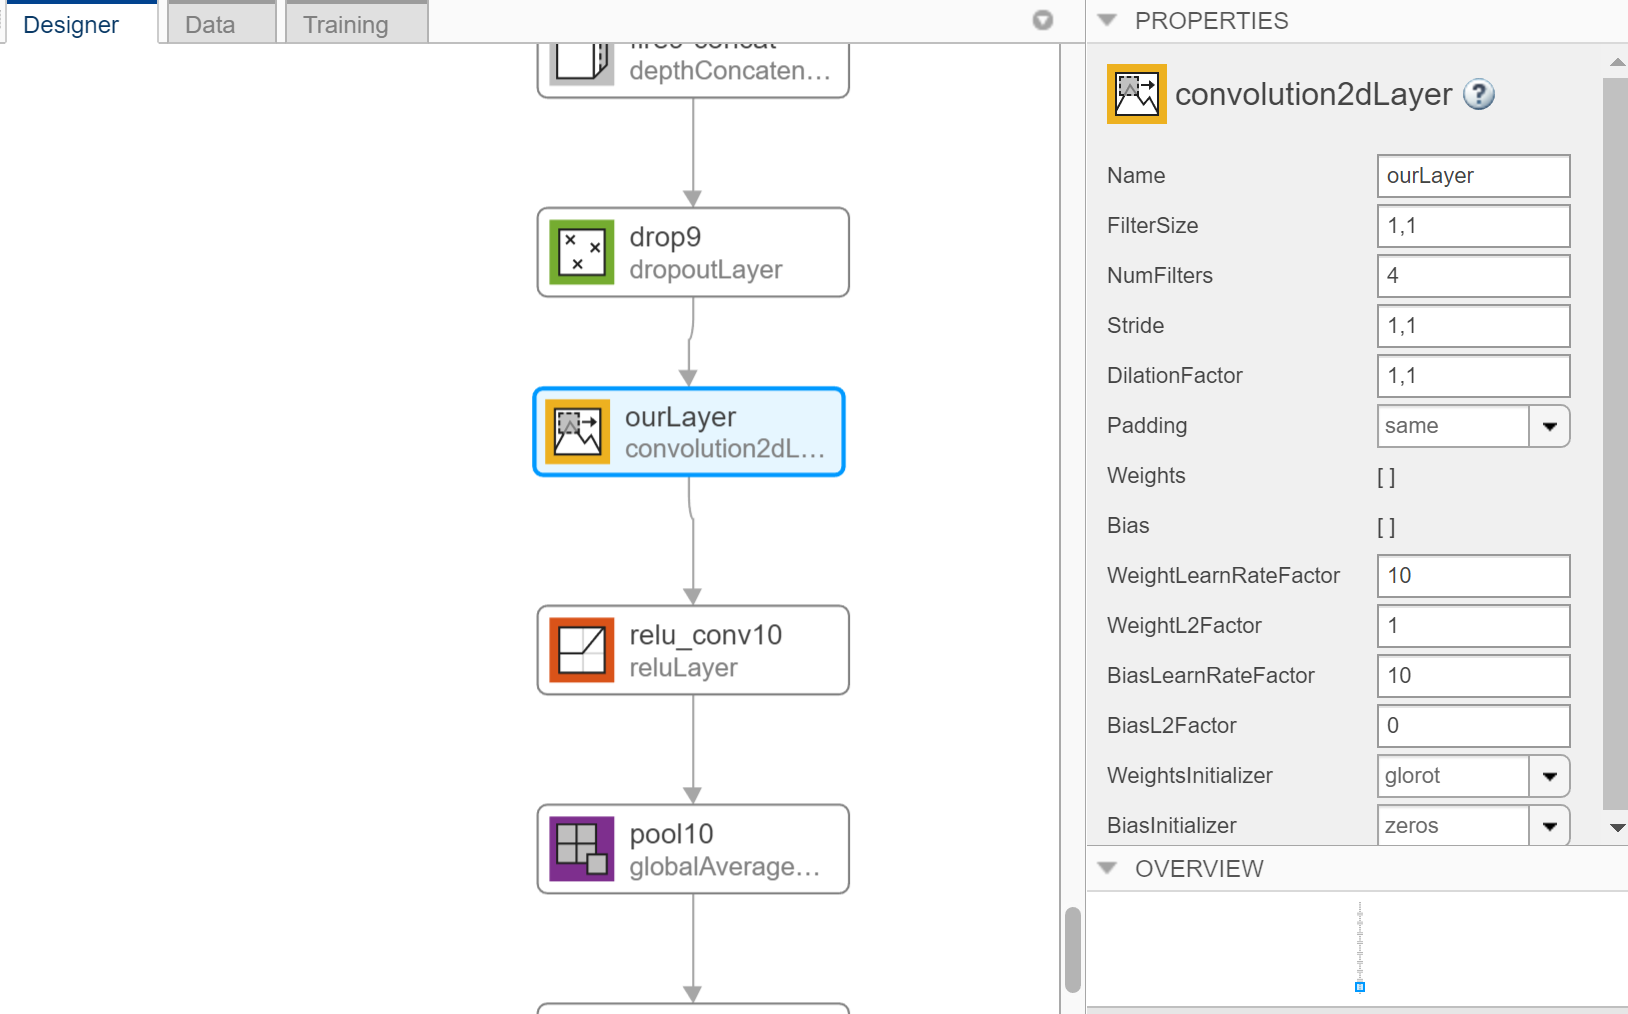

#### Swapping out the Classification Layer

Next replace the output layer. Scroll to the end of the **Layer Library** and drag a new `classificationLayer` onto the canvas. Delete the original output layer and connect your new layer in its place:

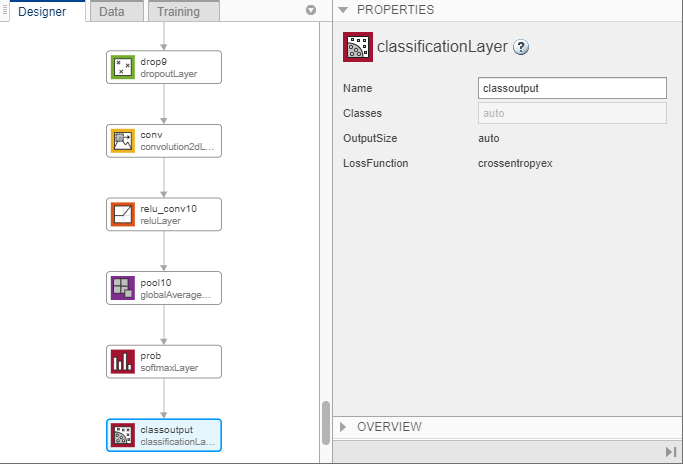

#### Setting Learning Rates for Your Network

For transfer learning to be more efficient than re-training an entire network, we need to set the learning rates for the layers we don't want to spend time retraining to something very low. We'll do that in the next step where we set Training options.

## Now Train Your Network Using Transfer Learning

To choose your training options, select the **Training** tab and click **Training Options**. As discussed, we'll want to set the initial learn rate to a small value to slow down learning in the transferred layers. In the previous step, you increased the learning rate factors for the 2-D convolutional layer to speed up learning in the new final layers. This combination of learning rate settings results in fast learning only in the new layers and almost no changes in the other layers.

For this example, set **InitialLearnRate** to `0.0001`, **ValidationFrequency** to 10, **MaxEpochs** to 10. (You can experiment with different values, depending on how powerful your computer is, but these will give you a good baseline. Setting **MiniBatchSize** to 32 is a reasonable starting point, but you can experiment with it later. (If you don't have an Nvidia GPU and are in a hurry, try setting MaxEpochs to something lower like 5 to end the training sooner).

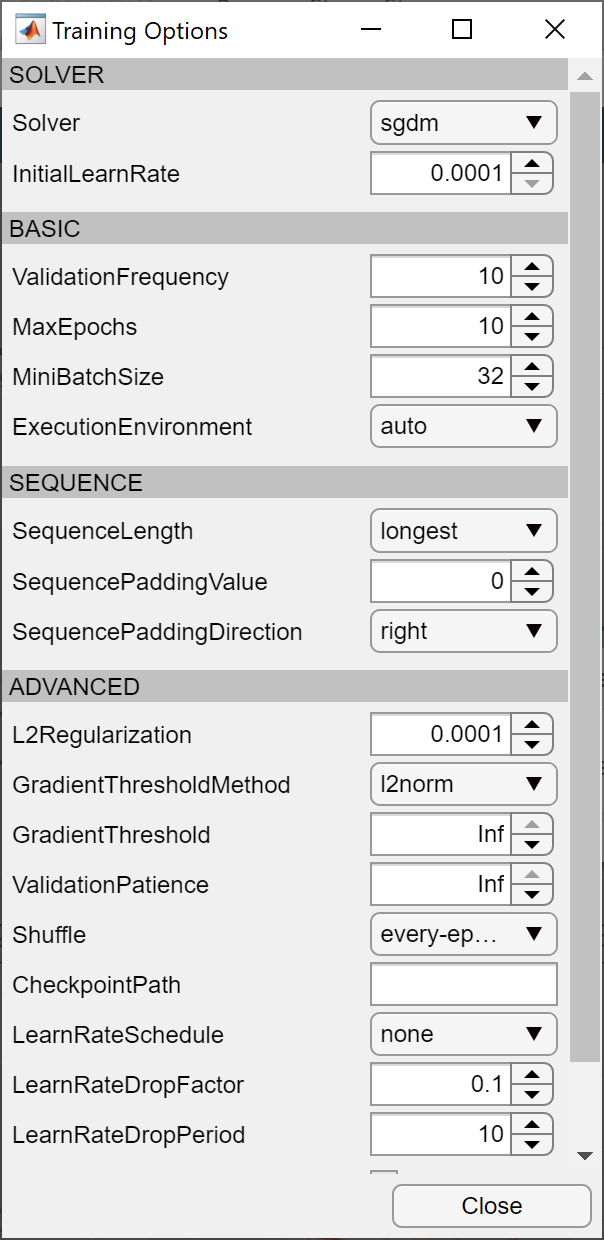

To train the network with the specified training options, click **Close, **take a deep breath, and then click **Train**. If all has gone well, your computer will be off and running training a network to recognize images from the camera you have designed!

Deep Network Designer allows you to visualize and monitor the training progress. After that, you can edit the training options and retrain the network, if required. The amount of time it takes to train the network is greatly affected by your computer configuration. Systems with an Nvidia GPU will train much more quickly than ones without.

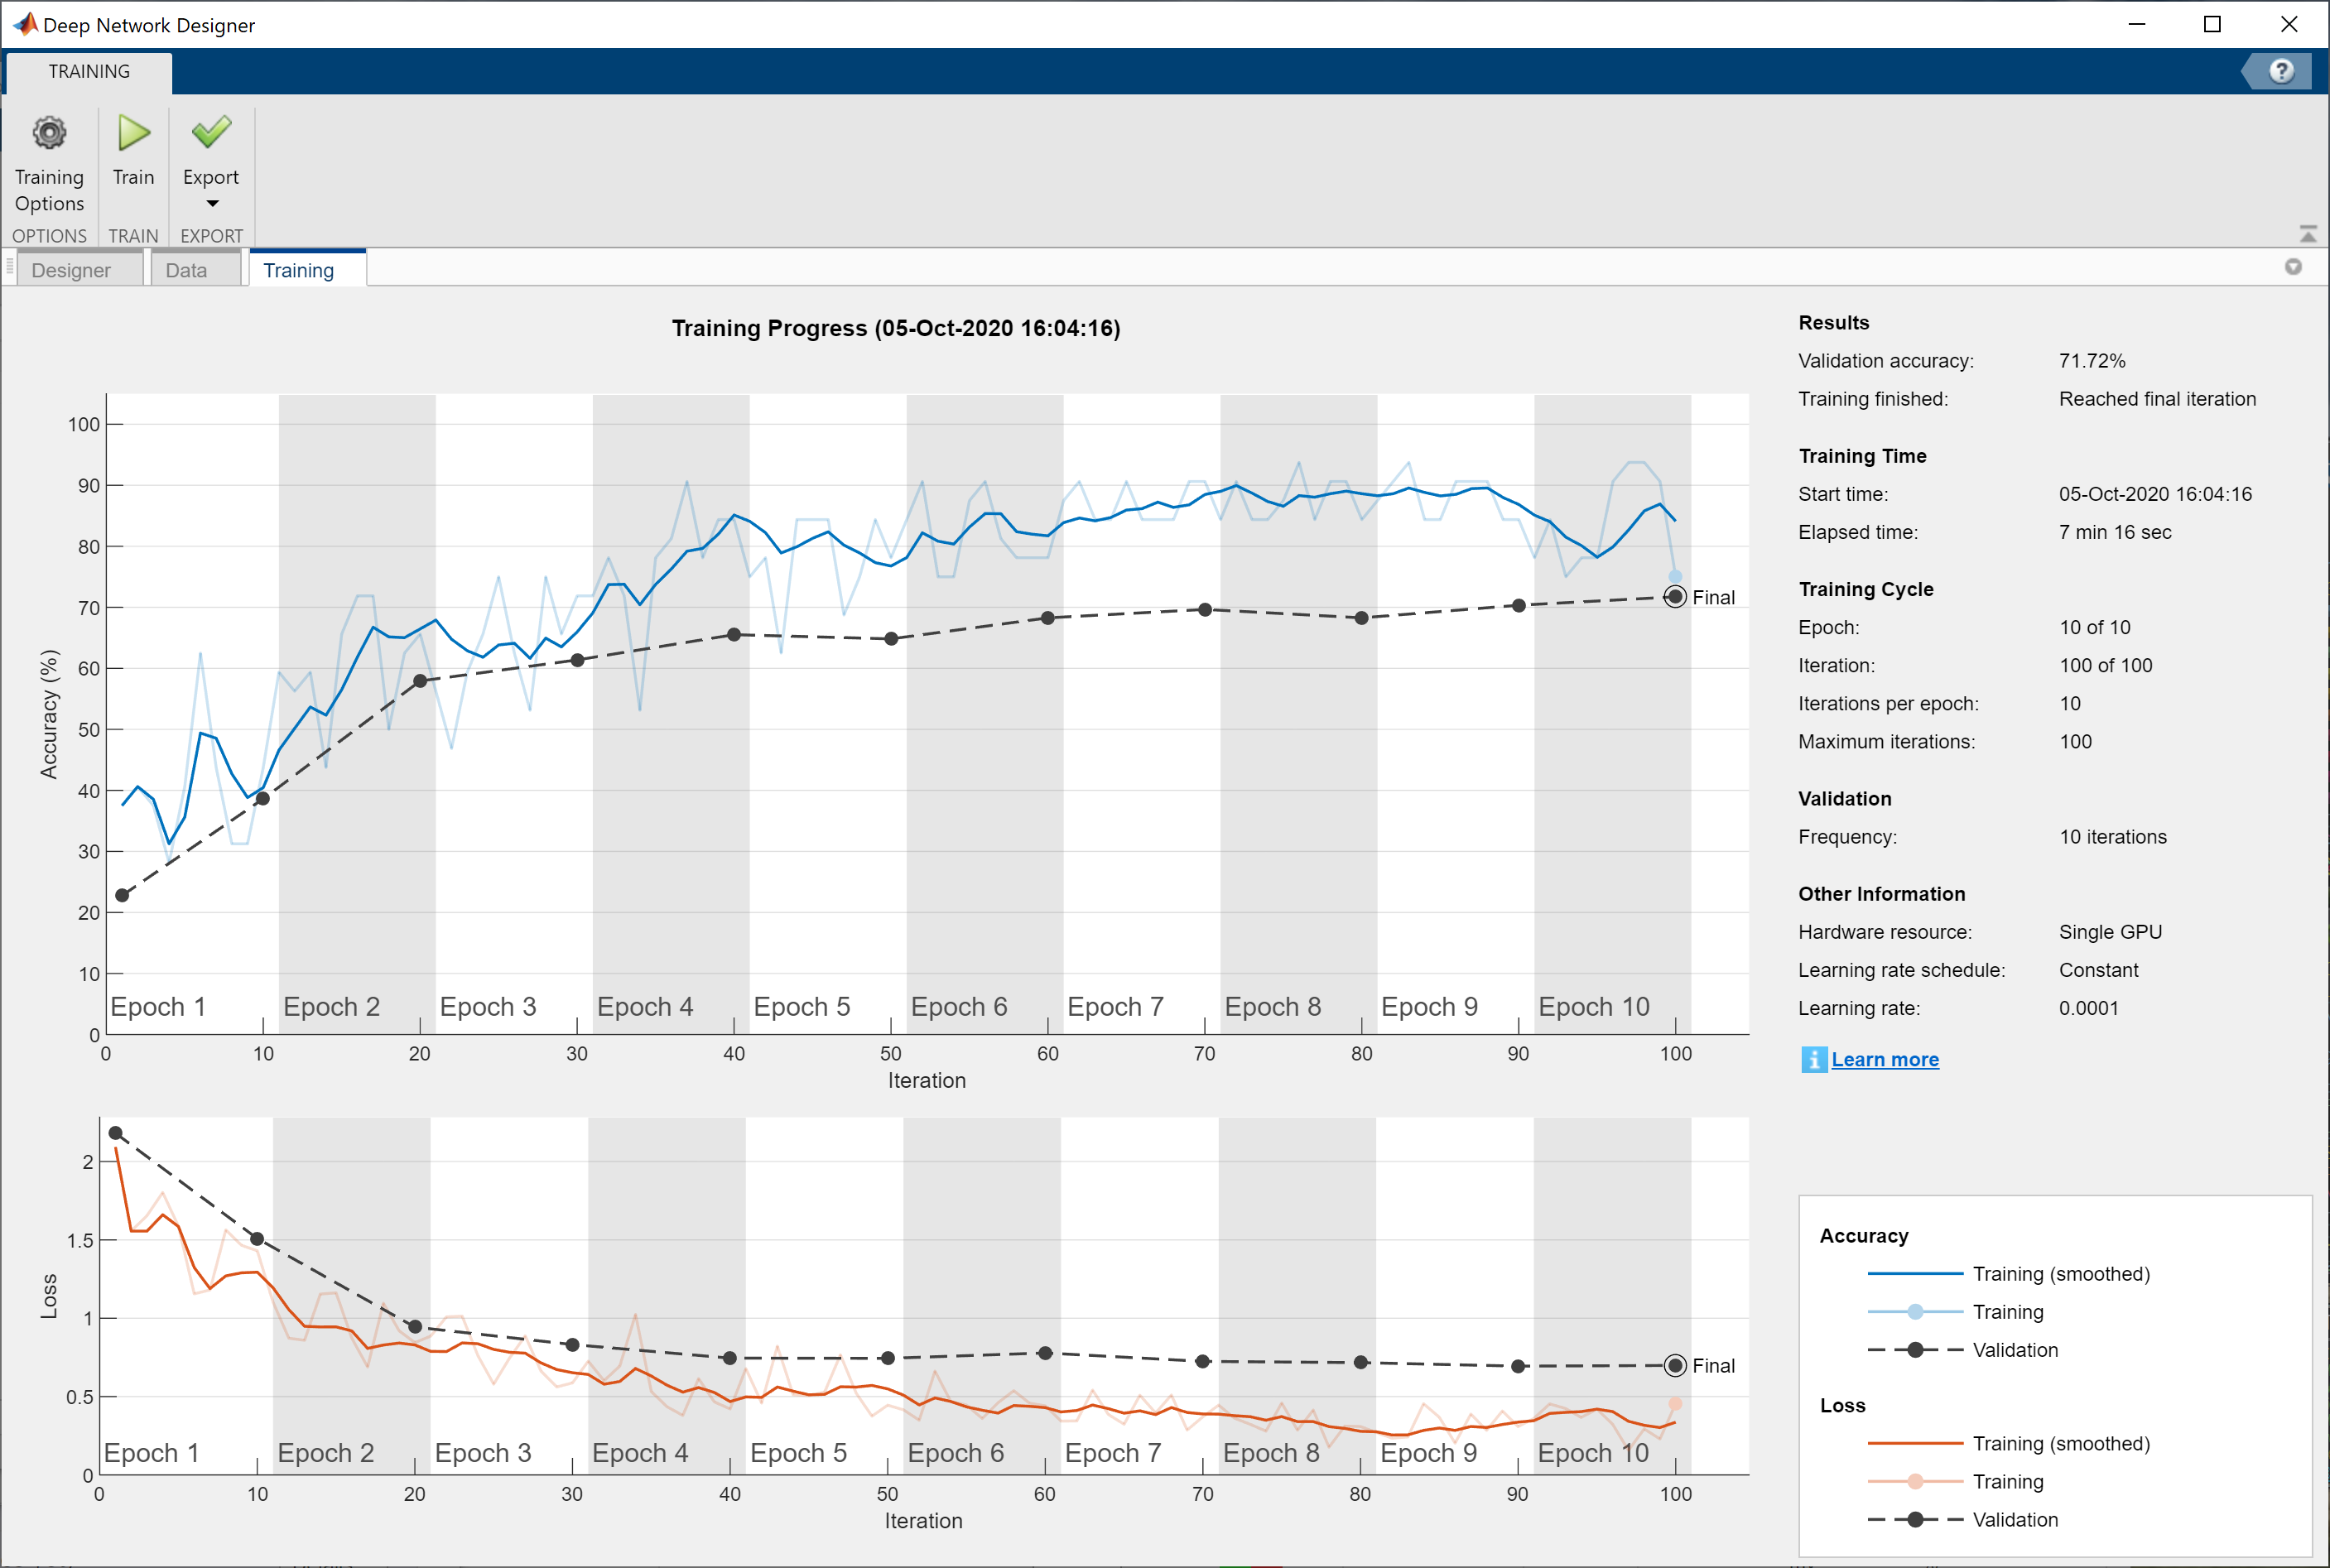

# The Fun Begins: Training on Your Camera Design

Okay, so we've seen that we can optimize a network by learning from a specific set of images. But we haven't done much imaging science yet. That's where your camera design comes in. What we do next is train a network with images as captured by your own virtual camera and see how well it does. That allows us to evaluate your novel camera design and see how it performs compared to a traditional baseline.

### Creating, Saving, and Loading a Camera Design

To do that, first, of course, you'll need to have a camera design. That's what ISET is for. You'll need Optics, a Sensor, and an Imaging Pipeline. You can create those using Matlab code that runs ISETcam functions or get an assist from the ISET AI Camera Design app. EIther way, you'll need to wind up with a camera design.

The simplest way to do that is to set the current optics, sensor, and IP in ISET to the ones you want. Our training script will automatically use them. If you simply want to experiment with transfer learning, the classifier script will create a default camera for you, so you can skip that step.

Once you have a camera design, you might want to save your camera design for later. Cameras can be saved as a Matlab data (.mat) file. If you've set your ISET session to have the optics, sensor, and IP that you want to use, the following code fragment will let you save them all together as a Camera Object in a local file:

% If you want to save a camera design for later use:
% first make a camera object that includes everything
camera = cameraCreate('current');
% Then we create a default location for saving our designs
cameraFolder = fullfile(isetRootPath, "local", "cameras");
if ~isfolder(cameraFolder)
    mkdir(cameraFolder);
end
% And let the user select a name for their design, then save it
[cameraFileName, cameraFilePath] = uiputfile(fullfile(cameraFolder,"*.mat"),"Choose a filename for your Camera");
if ~isequal(cameraFileName,0)
    vcSaveObject(camera, fullfile(cameraFilePath,cameraFileName));
end

Once you have you camera design loaded into ISET you can process your downloaded test image dataset as if it had been captured by your virtual camera. If you've saved a camera design using the code above, you can load it back with this code fragment:

cameraFolder = fullfile(isetRootPath, "local", "cameras");
if ~isfolder(cameraFolder)
    mkdir(cameraFolder);
end

[cameraFileName, cameraFilePath] = uigetfile(fullfile(cameraFolder,"*.mat"),"Select a saved Camera");
if ~isequal(cameraFileName,0)
    vcLoadObject('camera', fullfile(cameraFilePath,cameraFileName));
end

Or simply use the File menu in the ISET Camera Design app to save and load your camera designs.

ieCameraDesigner

# Evaluating Your Camera Design

To evaluate your camera design we'll use transfer learning to see how well your novel camera design performs compared to what is already out there. That starts with loading the current Camera parameters with your design (either using vcLoadObject or just making them the current value).

Then, we'll same expClassify function we use in the Camera Designer app. However, we'll only use it to create images captured through your simulated camera, not to classify them. We'll then feed those images to the network you have created in the Deep Network Designer to see how well it can learn from them.

Make sure you have set ourDataFolder to the location of your original image data, and then this code fragment will create a parallel "_IP" folder tree where your simulated images will live:

% Assume ourDataFolder is set to the location of our dataset, 
% either by running the code above or by the user setting it.
% We need to recurse of the sub-folders for each class, generating
% the IP-output for each image in a parallel folder structure
if ~isfolder(ourDataFolder)
    error("%s isn't a valid folder", ourDataFolder);
end
ourIPDataFolder = strcat(fileparts(ourDataFolder),"_IP");
if ~isfolder(ourIPDataFolder)
    mkdir(ourIPDataFolder);
end


It can take a long time to fully-simulate a camera image, so you might want to start out by limiting the number of images in each class that you simulate, while you experiment. By setting imagesPerClass to a value smaller than the total number in the dataset for each class you can speed up the simulation process.

The default dataset has about 120 images in each of 4 classes. It can take over an hour to simulate capturing all of them with an ISET camera. So by default we set imagesPerClass to 30, to speed things up. When you're close to knowing what you really want to do you can simply increase it. Even with a limited number of images per class, it can be a slow process to generate simulated images, so be patient.

imagesPerClass = 30;

subFolders = dir(ourDataFolder);

% get the current camera design, if pieces are missing, use the default
camera = cameraCreate('current');

Creating new oi (default)
Using current sensor monochrome_320_480_sensor
Creating new ip (default)


oiObj = cameraGet(camera, 'oi');
ipObj = cameraGet(camera,'ip');
sensorObj = cameraGet(camera,'sensor');

for ii = 1:numel(subFolders)
    ourFolder = subFolders(ii);
    if ourFolder.name(1) ~= "."
        ourIPDataSubFolder = fullfile(ourIPDataFolder, ourFolder.name);
        % first blush just use default camera parts
        fprintf(strcat("Processing: ", ourFolder.name, "\n"))
        expClassify('ipOutputFolder', ourIPDataSubFolder, 'classifier', '', ...
            'imageFolder', fullfile(ourFolder.folder, ourFolder.name),...
            'maxImages', imagesPerClass, 'progDialog', '', ...
            'oi', oiObj, 'ip', ipObj, ...
            'sensor', sensorObj);
    end
end

Processing: cheetah
Processing: hyenas
Processing: leopards
Processing: lions


fprintf("Now you should be able to find your processed data here:\n %s\n", ourIPDataFolder);

Now you should be able to find your processed data here:
 B:\iset\isetcam\local\data\DavidCardinal_AfricanMammals_IP


### Testing How Well Your Camera Design Works

To evaluate your camera design and see how well it trains simply load the new data into the Deep Network Designer and re-run the training process. So that you don't confuse the two training sessions, when you load the new data, select to discard the previous training results -- so that the network training starts over.

To do that, use the Data tab of the Deep Learning Designer to load the output of ourIPDataFolder as the image data set. 

NOTE: If you have left imagesPerClass at the default of 30, you may want to set Epochs (the number of times your network will process your dataset) to a higher number than 10 in the Training Options, as with 30 images per class, it takes more iterations through the data to train the network. Setting Epochs to 20 or 30 will give you better results.

Now go back to the Training tab and select "Train." You'll be asked if you want to discard the previous results. In this case the answer is yes, because we want to start over retraining from the default Squeezenet.

If you use the default optics, sensor, and IP in ISET and process all of the test images your results might look something like this (if you have maxImages set, then you'll see a bit less data):

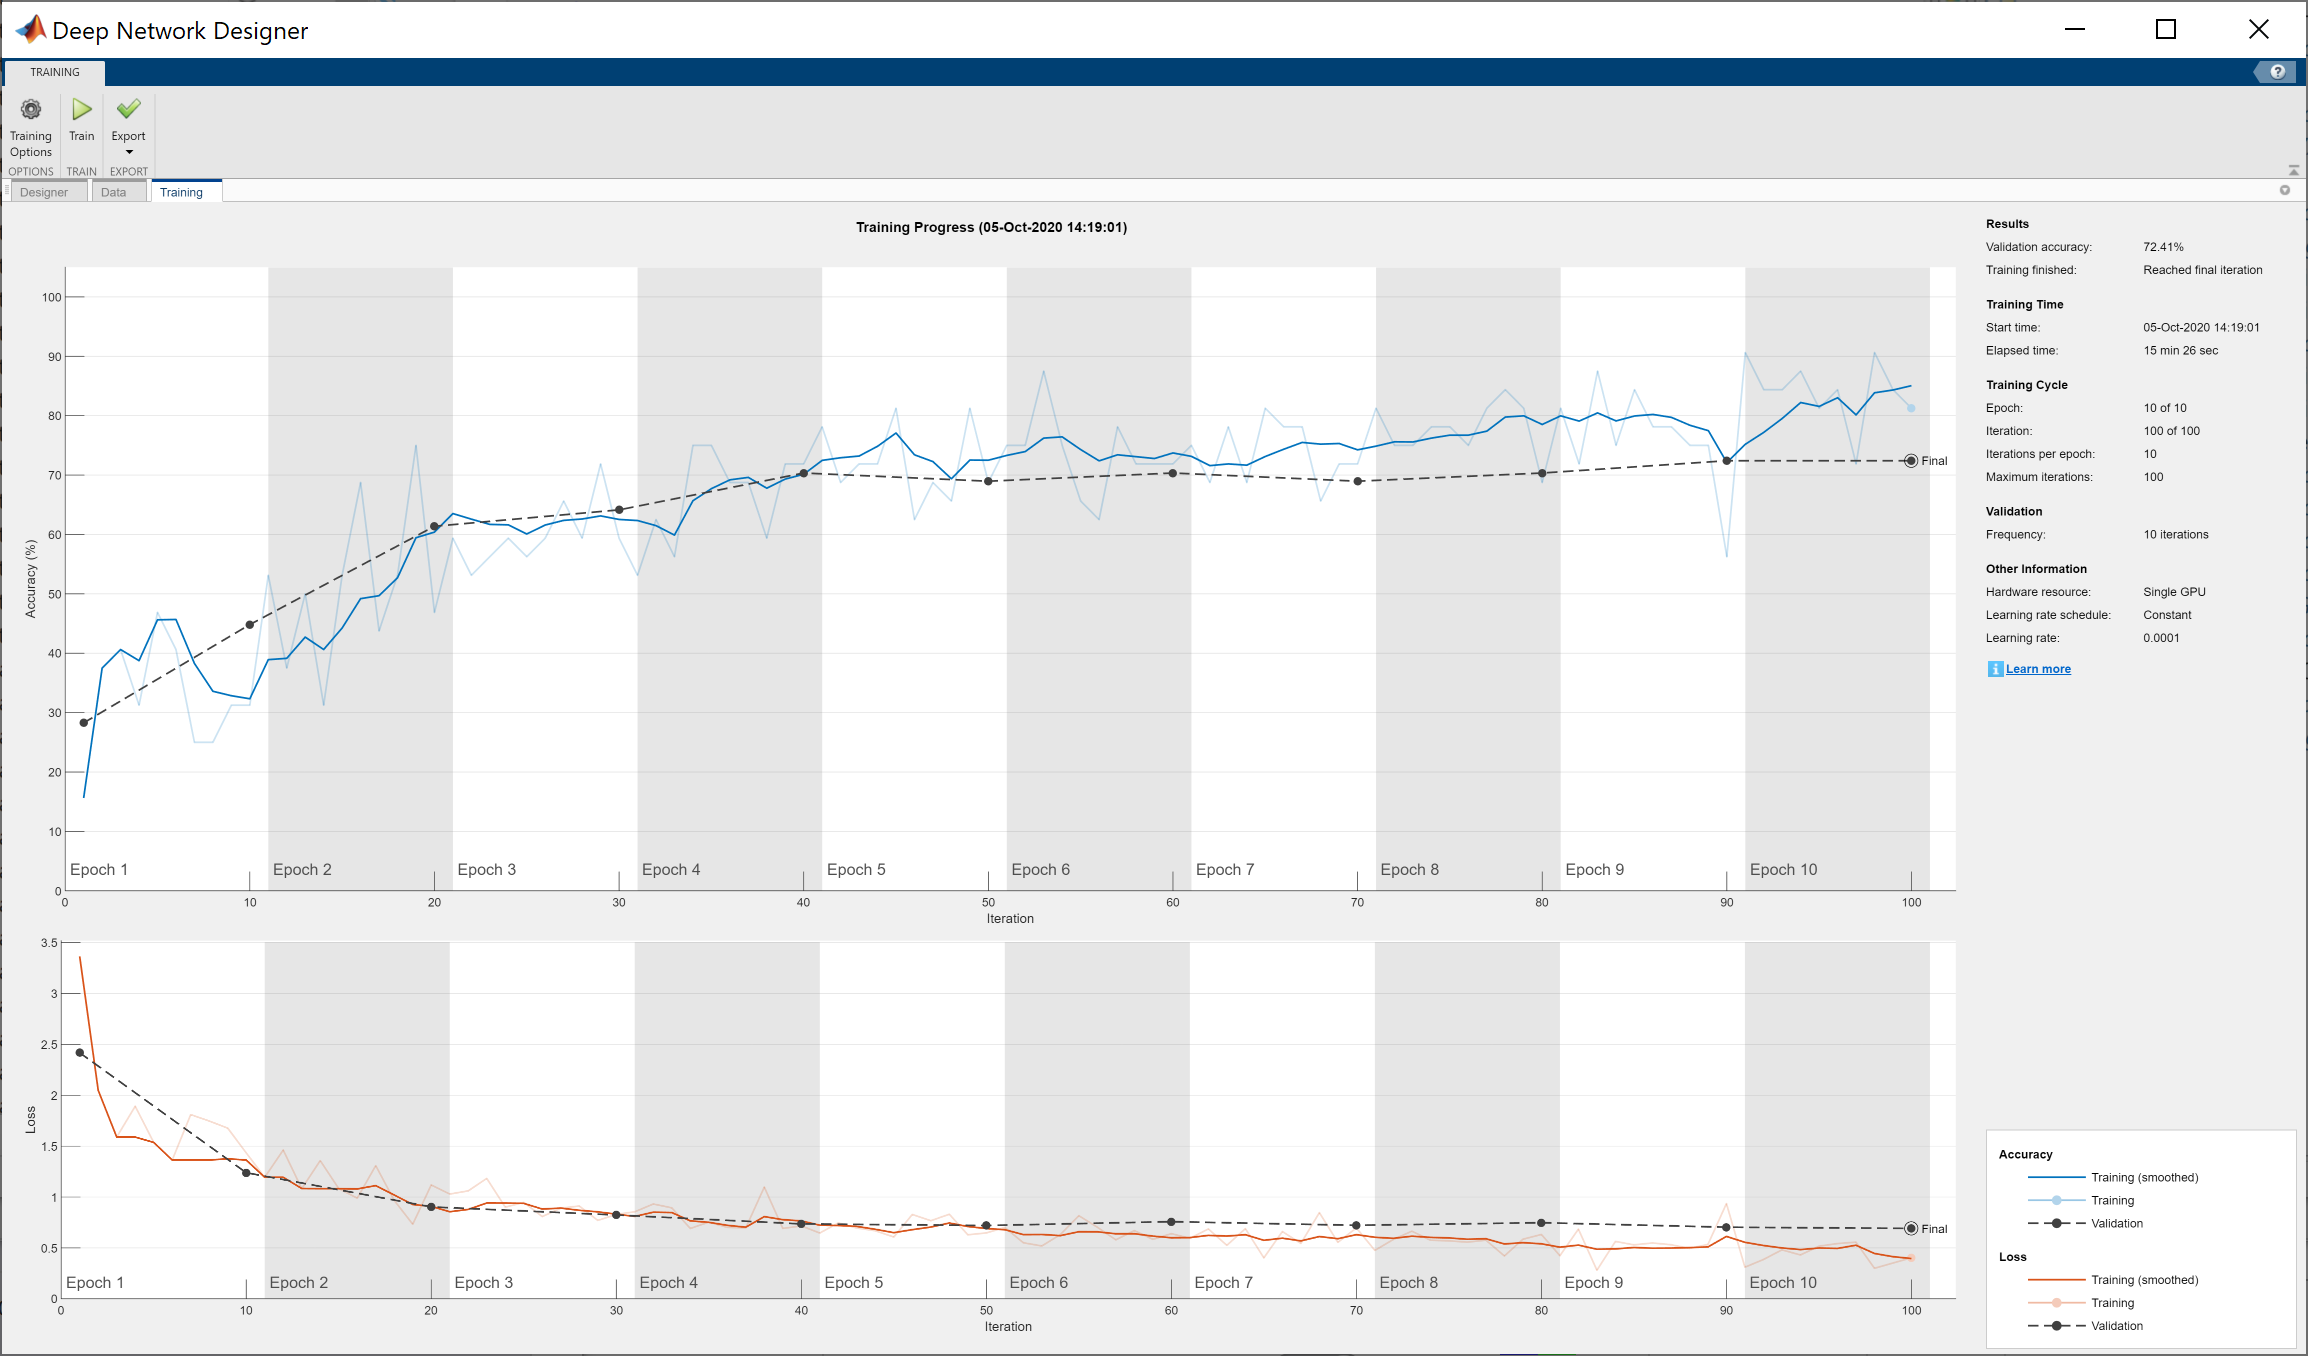

## Export and Saving Results

You can save an un-trained version of your modified network by using the Export button on the Designer tab. That is helpful if you don't wan to have to repeat the edits you've made to the base network you're using. Export will put the network in a variable in your Workspace that you can save to your computer using Matlab's save() command.

To save your trained network, including the resulting weights learned during the training, on the **Training** tab, select **Export** > **Export Trained Network and Results**. Deep Network Designer exports the trained network as the variable `trainedNetwork_1` and the training info as the variable `trainInfoStruct_1`. Just like the un-trained network these can be saved to your computer using save().

If you want to go beyond the Designer UI you can also generate MATLAB code, which recreates the network and the training options used. On the **Training** tab, select  **Export** > **Generate Code for Training**. Examine the MATLAB code to learn how to programmatically prepare the data for training, create the network architecture, and train the network.

## Appendix:

## Just like Athletes, Neural Networks Can Over-Train

Especially if you don't have a large number of a wide variety of images in your training set, it is possible that your net can go beyond recognizing their features and essentially just start to memorize them -- the way a student might with flashcards. In both cases, the problem is that real learning isn't happening.

For neural networks, this problem is caled over-fitting, and is fairly easy to diagnose. By keeping some of our dataset separate and not using it for training, we can see how well the network does for real. That's called our Validation data. Matlab makes it easy to keep some data separate (above we chose 30%) and then it runs validation in parallel. If you see the training accuracy continue to increase while the validation accuracy doesn't, then you've probably reached the limits of how much you can train that particular network with the dataset you have. Here's an example of what that looks like:

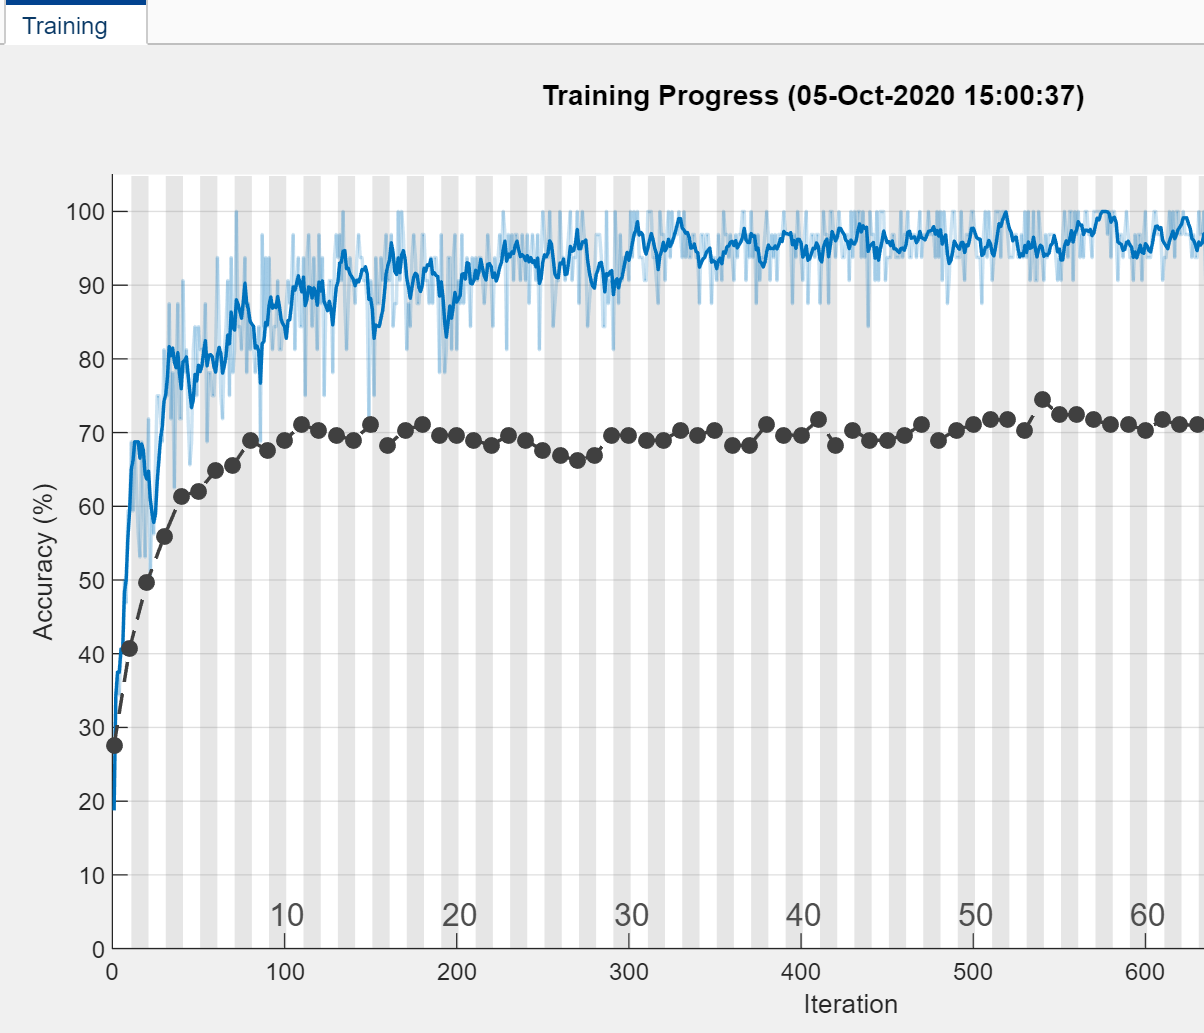

*Some images courtesy of The MathWorks, Inc.*